# Matlab Graph Generate EPS postscript figures in matlab

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**MEconTools**](https://fanwangecon.github.io/MEconTools/)** Repositories**

## Properly Save EPS with Scatter and Other Graphing Methods: Renderer = Painters

scatter plot saving as eps seems to only work when Renderer is set to Painters

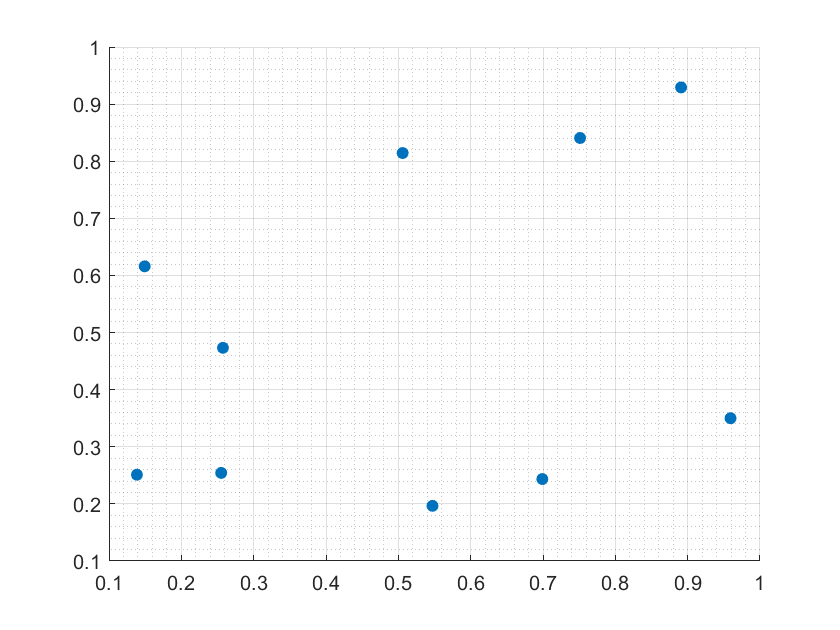

fl_fig_wdt = 3;
fl_fig_hgt = 2.65;

figure('PaperPosition', [0 0 fl_fig_wdt fl_fig_hgt], 'Renderer', 'Painters');
x = rand([10,1]);
y = rand([10,1]);
scatter(x, y, 'filled');
grid on;
grid minor;

st_img_path = 'C:/Users/fan/M4Econ/graph/export/_img/';
st_file_name = 'fs_eps_scatter_test';

% eps figure save with tiff preview
print(strcat(st_img_path, st_file_name), '-depsc', '-tiff');